n_images = 9;
dataset_path = './datasets/newpiv2/';
rgb_filename_format = strcat(dataset_path,'rgb_image_%d.png');
depth_filename_format_mat = strcat(dataset_path,'depth_%d.mat');
depth_filename_format = strcat(dataset_path,'depth_%d.png');

## Convert depth files from .mat to .png

for i=1:n_images
    d_struct=load(sprintf(depth_filename_format_mat,i));
    imwrite(d_struct.depth_array,sprintf(depth_filename_format,i), 'Mode', 'lossless');
end

## Input data

imgseq = (struct('rgb', '', 'depth', '')); % init array of structures
for i=1:n_images
    imgseq(i) = struct( ...
        'rgb', sprintf(rgb_filename_format,i), ...
        'depth', sprintf(depth_filename_format,i));
end

cam_params = load('materials/calib_asus.mat');
cam_params = struct( ...
    'Kdepth', cam_params.Depth_cam.K, ...
    'Krgb', cam_params.RGB_cam.K, ...
    'R', cam_params.R_d_to_rgb,...
    'T', cam_params.T_d_to_rgb);


## Run

k = 5;
[transforms, XYZ, RGB] = new_rigid_transforms(imgseq, k, cam_params);

## Point cloud

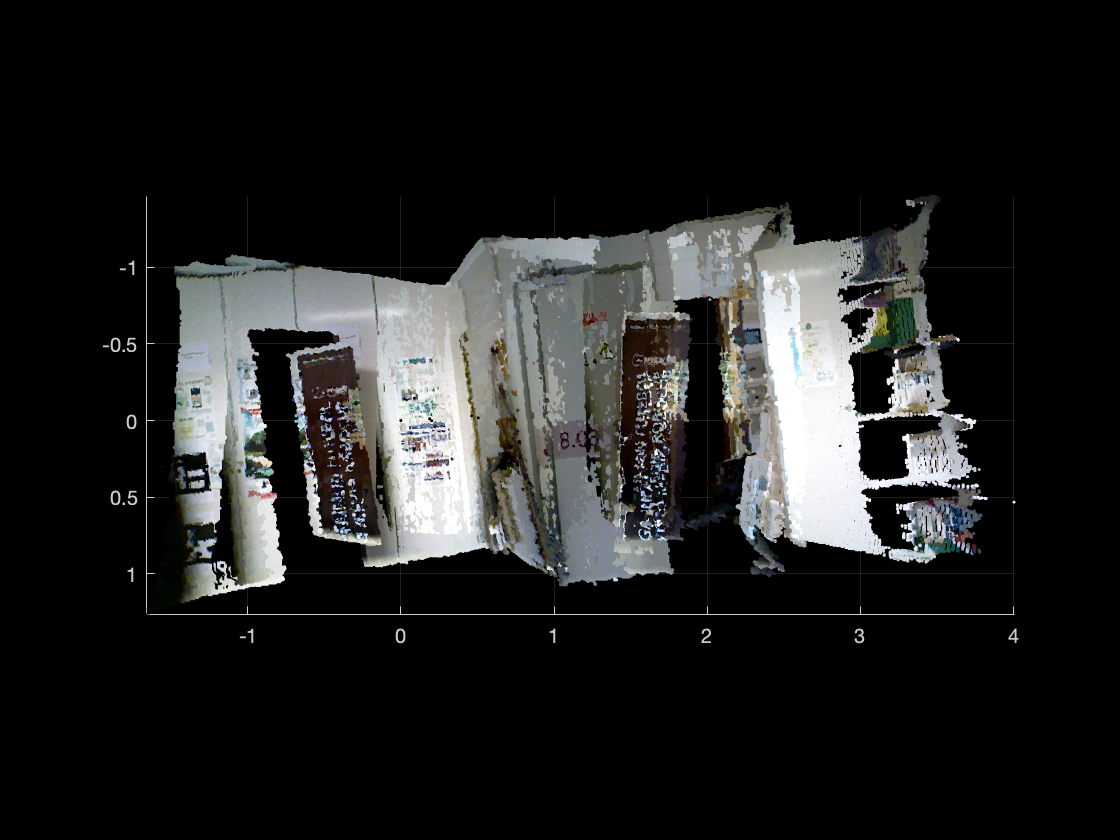

figure
point_cloud = pointCloud(XYZ);
point_cloud.Color = RGB;
showPointCloud(point_cloud);
view([0,0,-1])